# 更改刻度值位置和标签

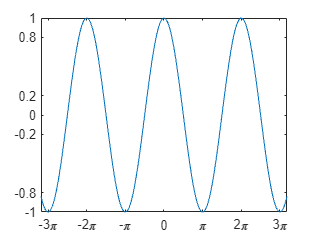

x = linspace(-10,10,200);
y = cos(x);
plot(x,y)

% 更改沿 x 轴和 y 轴的刻度值位置。将这些位置指定为一个由递增值组成的向量。这些值无需等距。
% 此外，还要更改沿 x 轴的每个刻度值关联的标签。并用一个字符向量元胞数组来指定刻度标签。
% 要在标签中包含特殊字符或希腊字母，可使用 TeX 标记，例如用 \pi 表示 π 符号。
xticks([-3*pi -2*pi -pi 0 pi 2*pi 3*pi])
xticklabels({'-3\pi','-2\pi','-\pi','0','\pi','2\pi','3\pi'})
yticks([-1 -0.8 -0.2 0 0.2 0.8 1])

## 旋转刻度标签

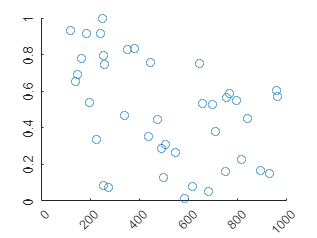


x = 1000*rand(40,1);
y = rand(40,1);
scatter(x,y)
xtickangle(45)
ytickangle(90)

## 更改刻度标签格式

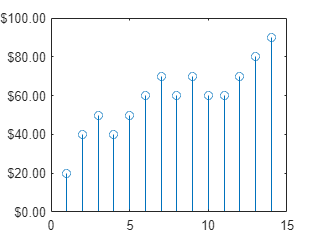

profit = [20 40 50 40 50 60 70 60 70 60 60 70 80 90];
stem(profit)
xlim([0 15])
ytickformat('usd')

% 用于分别控制各个坐标轴的标尺对象
ax = gca;
ax.XAxis 

ans =   NumericRuler - 属性:

             Limits: [0 15]
              Scale: 'linear'
           Exponent: 0
         TickValues: [0 5 10 15]
    TickLabelFormat: '%g'

  显示 所有属性


## 使用标尺对象控制指数标签中的值

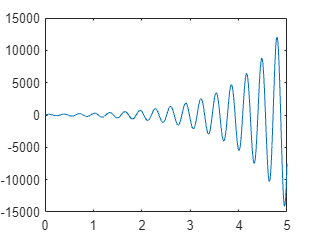

ax =   Axes - 属性:

             XLim: [0 5]
             YLim: [-15000 15000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  显示 所有属性


x = linspace(0,5,1000);
y = 100*exp(x).*sin(20*x);
plot(x,y)

ax = gca;
ax.YAxis.Exponent = 2;
% 将指数值更改为 0，使刻度标签不使用指数记数法
ax.YAxis.Exponent = 0